# Simulating Trajectory Noise

Objective: This script will show you how the process noise affects a robot's trajectory and why dead reackoning is not an accurate solution for robot localization. 

Helper Functions used in this exercise:

- *plotTraj *plots the map, the true trajectory, and the noisy trajectory

Execise:

First, we'll simulate a trajectory with process noise to show how this uncertainty affects the movement of the robot.

Load map

map = load('MAP102.txt');

Define robot starting location (just x,y) and the time step

robotXY = [-1.5; -.5];
dt = 0.05;

First start with control input (u = [Vx;Vy]) Travel east with speed of 1 m/s for 2 seconds, then travel west with a speed of 0.5 m/s for 2 seconds. 

**COMPLETE THE CODE BELOW**

time = 2; %seconds
N = round(time/dt); % Number of timesteps for two seconds
Vx = [ones(1,N), -0.5*ones(1,N)]; % 1 velocity for first second, -0.5 velocity for next second (row vector length N)
Vy = [zeros(1,N), zeros(1,N)]; % 0 velocity for first second, 0 velocity for next second (row vector length N)
u = [Vx; Vy];  % Concatenate into a single 2 x N control matrix

Matrix A and B define the kinematic equations for a holonomic robot $x_{t+1} = Ax_t + B u_t$. 

**COMPLETE THE CODE BELOW**

A = [1,0;0,1];
B = [dt,0;0,dt];

The Matrix R is the covariance matrix for the process noise, the higher the variance the less accurate dead reckoning will be.

**COMPLETE THE CODE BELOW**

variance = .14; %Change value here
R = [variance 0; 0 variance];

Here we generate a noisy robot trajectory by looping through the control inputs u and applying the kinematic updates for each time step. The robotXYtraj is the predicted path using dead reckoning, while the robotXYtrajNoisy is the 'true' path the robot takes.

robotXYtraj = zeros(2,1+length(u)); % Allocate
robotXYtrajNoisy = zeros(2,1+length(u));
robotXYtraj(:,1) = robotXY; % Initialize
robotXYtrajNoisy(:,1) = robotXY;


**COMPLETE THE CODE BELOW**

for i = 1:length(u)
    robotXYtraj(:,i+1) = A*robotXYtraj(:,i) + B*u(:,i); % Kinematics without noise
    robotXYtrajNoisy(:,i+1) = A*robotXYtrajNoisy(:,i) + B*u(:,i) +  ...
                              dt.*sqrt(R)*randn(2,1); % Kinematics with noise
end

Plot the resulting noisy trajectory versus the non-noisy one. Adjust the variance process noise.

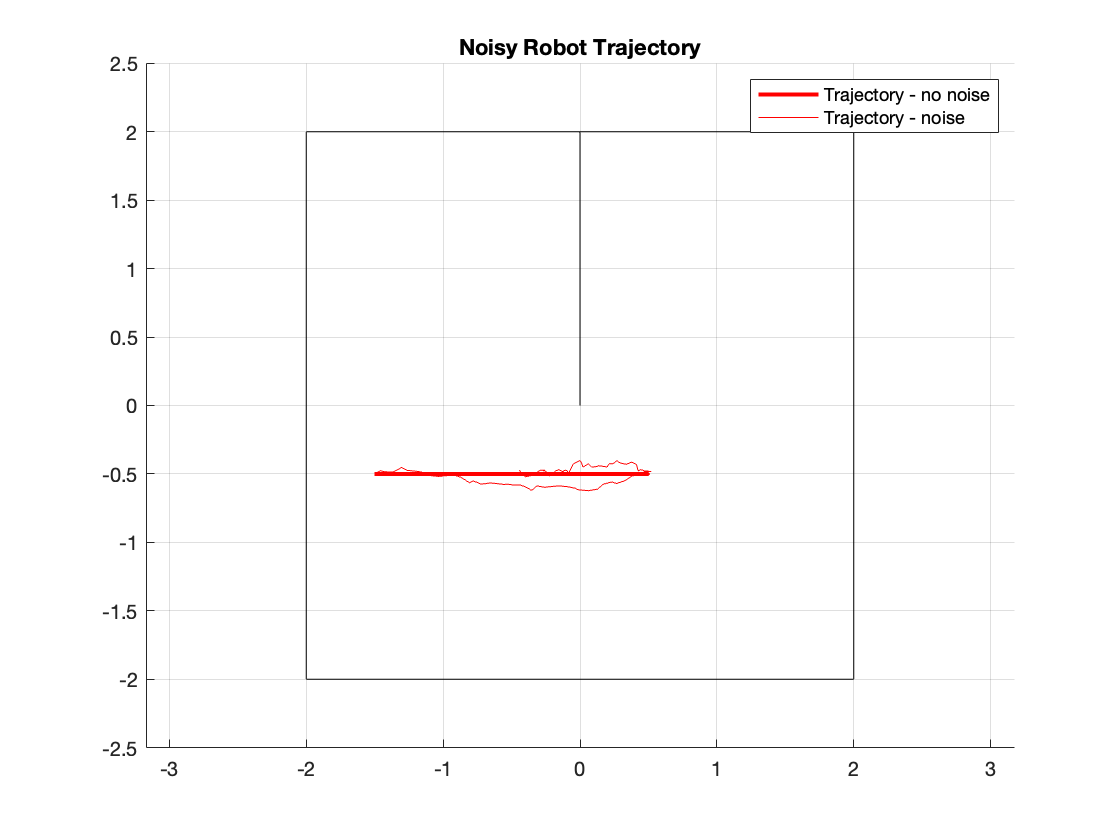

plotTraj(map, robotXYtraj, robotXYtrajNoisy); 

Expected Results: The plot should depict 2 different trajectories, one true trajectory (that looks like a perfect line) and a more realistic trajectory with noise. 

Check your Comprehension: Do your results make sense? Compare the noisy trajectory with the true trajectory. What do you notice about the trajectory as you change the variance?